# Dataset generation

This script generates the dataset for training a Neural Net able to performe source localization. The Nerual Net and the experiment setup are described by the paper *Deep learning assisted sound source localiztion using two orthogonal first-order differential microphone arrays *[Nian Liu, Huawei Chen, Kunkun Songgong, et al].

We used **rir-generator** to simulate the room acoustics. 

In order to work properly, this script needs a compiled rir-generator (mex file) and this folder structure:  

fprintf(".\n├── TIMIT/\n│   ├── TRAIN\n│   └── TEST\n├── MATLAB_TRAIN\n├── MATLAB_VAL\n├── MATLAB_TEST30\n├── MATLAB_TEST10\n├── RECEIVER_POS\n├── ROOM_VOLUME\n└── SOURCE_DISTANCE\n");

.
├── TIMIT/
│   ├── TRAIN
│   └── TEST
├── MATLAB_TRAIN
├── MATLAB_VAL
├── MATLAB_TEST30
├── MATLAB_TEST10
├── RECEIVER_POS
├── ROOM_VOLUME
└── SOURCE_DISTANCE


Where the TIMIT/ folder contains the TIMIT dataset.

% Script init
close all
clearvars
clc

## Room simulation parameters

In this cell we initialize all the parameters used to simulate the room acoustics with rir-generator. In particular, for this experiment, the 4 microphones are placed in the center of the room at a height of 1.5 [m].

c = 340;                     % Sound velocity (m/s)
dim = 3;                     % Room dimensions
T60 = 0.3;                   % Reverberation time (s)
n = 4096;                    % Number of samples
mtype = 'omnidirectional';   % Type of microphone
order = -1;                  % -1 = maximum reflection order
orientation = 0;             % Microphone orientation (rad)
hp_filter = 0;               % 0 = disable high-pass filter
room_dim = [9.64 7.04 2.95]; % Room dimensions [x y z] (m)

d = 0.04;   % Diameter of the microphone array
mic_center = [room_dim(1)/2 room_dim(2)/2 1.5];
radius = 1.5; % Distance from the center of the microphones
r = [mic_center(1) + d/2, mic_center(2),       mic_center(3);   % Receivers positions (m)
     mic_center(1),       mic_center(2) + d/2, mic_center(3);   % [x_1,  y_1,  z_1;  
     mic_center(1) - d/2, mic_center(2),       mic_center(3);   %  x_2,  y_2,  z_2; 
     mic_center(1),       mic_center(2) - d/2, mic_center(3);]; %  ...]   

In the following arrays we save the canidate Directions of Arrival (DOA) for two different resolutions:

- **30°**: subidividing $[-\pi, \pi]$ with this resolution generates 12 classes

- **10°**: subidividing $[-\pi, \pi]$ with this resolution generates 36 classes

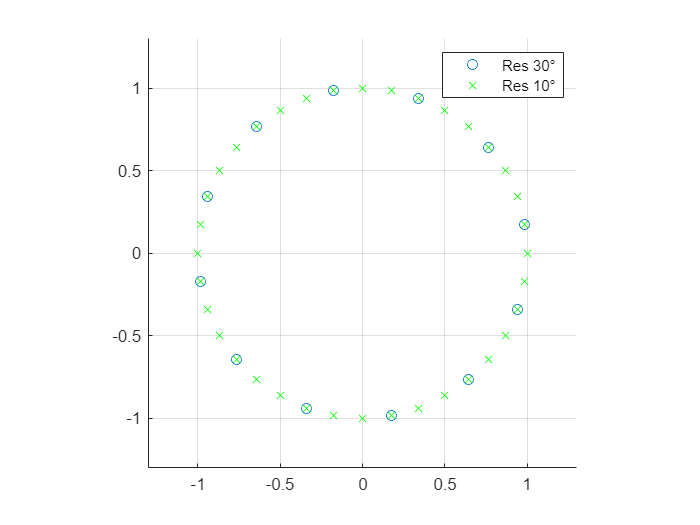

% Generating the candidate sources' locations in [-pi,pi] for each resolution  
K30 = 12; % Resolution 30° --> 12 classes
res30 = [190:30:340 10:30:160] / 360 * 2 * pi; % in [rad]

K10 = 36; % Resolution 10° --> 36 classes
res10 = [180:10:350 0:10:170] / 360 * 2 * pi; % in [rad];

figure;
scatter(cos(res30), sin(res30))
hold on
scatter(cos(res10), sin(res10),'x','g')
grid on
pbaspect([1 1 1])

xlim([-1.3 1.3])
ylim([-1.3 1.3])
legend(['Res 30°'; 'Res 10°'])

## Train dataset generation

To generate the dataset for the training, first we randomly select 300 sentences from the TIMIT/TRAIN dataset. And since we want to reach a dataset size of 6000 datapoints, we locate 1 sentence in 30 different DOAs.

fs = 16000;                 % Sample frequency (samples/s)
maxDuration = 2;            % Max duration of a sentence (s)

% Retrieving all the wav files in the TRAIN directory of the TIMIT dataset
folder = 'TIMIT/TRAIN';
fileListTrain = dir(fullfile(folder, '**', '*.wav'));

% Examples of file names
for i = 1:10
    disp(fileListTrain(i).name)
end

SA1.WAV
SA2.WAV
SI1392.WAV
SI2022.WAV
SI762.WAV
SX132.WAV
SX222.WAV
SX312.WAV
SX402.WAV
SX42.WAV


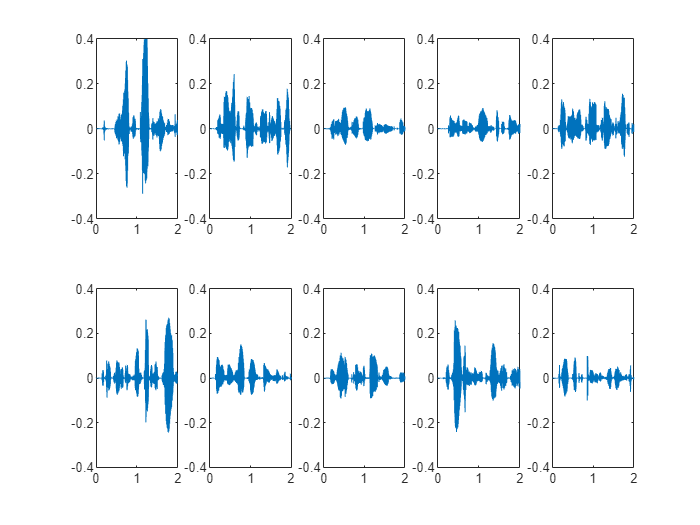

numSelectedSentencesTrain = 300; % Number of sentences drawn from the TIMIT dataset

% Randomly selecteing the indexes of the sentences
rng(21);
randIndexesTrain = randi([1 length(fileListTrain)],1,numSelectedSentencesTrain);

% Extracting the audio data of the randomly selected sentences in a NxM matrix
% where N are the number of samples and M the number of sentences --> column-wise read of the audio data
audioSamples = extractAudio(fileListTrain, randIndexesTrain, numSelectedSentencesTrain, maxDuration, fs);

% Dataset exploration
time = (0:1:fs*maxDuration - 1)  / fs;
for i = 1:10
    subplot(2,5,i)
    plot(time, audioSamples(1:fs*maxDuration,i))
    ylim([-0.4 0.4])
end 

Now we randomly generate all the DOAs: 

trainDatasetSize = 6000; % Size of the simulated dataset

% Each sentence will be associated with N different Direction Of Arrivals
DOASxSentence = trainDatasetSize / numSelectedSentencesTrain; % Number of DOAs for each sentence

% Randomly generating the DOAs for each data point in the dataset
randomDOAS = rand(trainDatasetSize, 1) * 2 * pi; % in [rad]

By using the function **rand **in $(0, 2\pi)$, we are sure to span all the angles with equal probability over the range. Hence we are generating a balanced dataset.

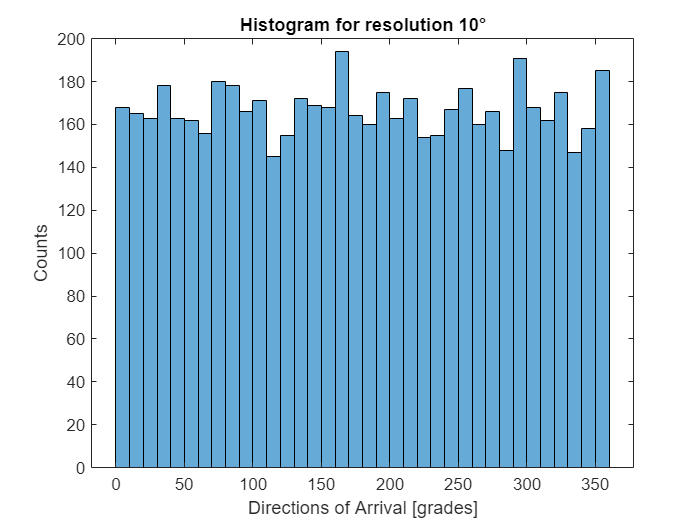

% Plotting the histogram of the randomly generated DOAs counting for bins
% of width 10°, e.g. 0°-10° | 10°-20° | ... | 350°-360°
figure;
histogram(randomDOAS/(2*pi)*360, [0 res10(19:end)  res10(1:18) 2*pi]/(2*pi)*360)
title('Histogram for resolution 10°')
xlabel('Directions of Arrival [grades]')
ylabel('Counts')

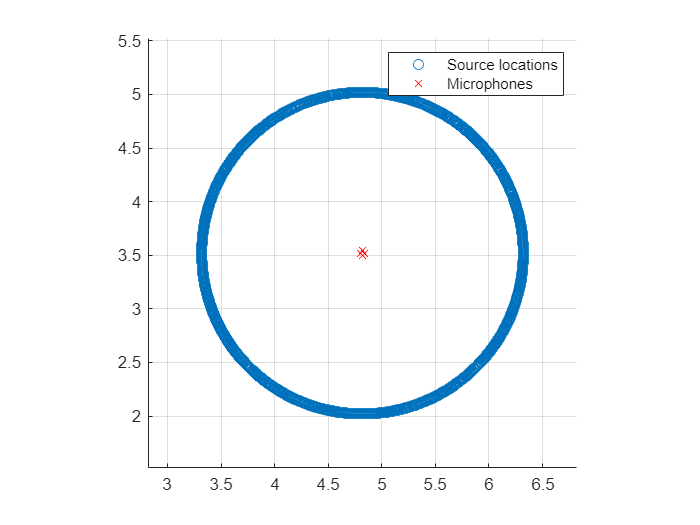

% Converting the DOAs in [x,y] positions over the microphones' plane

radius = 1.5; % Distance from the center of the microphones

sourceCoordinates = zeros([trainDatasetSize,2]); % First column is x-axis, second column is y-axis
for i = 1:trainDatasetSize
    sourceCoordinates(i,1) = mic_center(1) + radius * cos(randomDOAS(i)); % cos --> x coordinate
    sourceCoordinates(i,2) = mic_center(2) + radius * sin(randomDOAS(i)); % sin --> y coordinate
end

% Plotting the microphones' plane
figure;
scatter(sourceCoordinates(:,1), sourceCoordinates(:,2))
hold on
scatter(r(:,1), r(:,2), 'x','r', 'LineWidth', 0.5)
grid on
pbaspect([1 1 1])
legend({'Source locations', 'Microphones'})
lim = 2;
xlim([mic_center(1)-lim mic_center(1)+lim])
ylim([mic_center(2)-lim mic_center(2)+lim])

Generating the dataset:

generateDataset('MATLAB_TRAIN', audioSamples, numSelectedSentencesTrain, DOASxSentence, trainDatasetSize, randomDOAS, res30, res10, sourceCoordinates, c, fs, r, room_dim, T60, n, mtype, order, dim, orientation, hp_filter)

## **Validation dataset generation**

We follow the same procedure for the generation of the validation set (see previous comments). But now we consider 100 sentences, each associated to 10 DOAs. This lead to the generation of a dataset of size 1000.

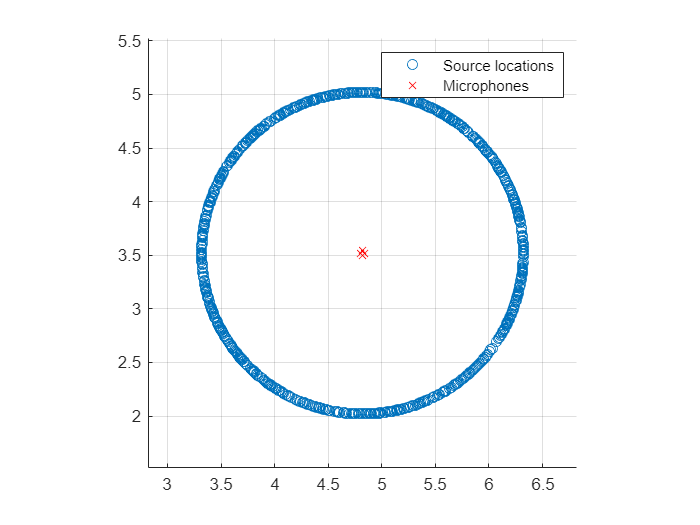

fileListVal = fileListTrain; % Still selecting the sentences from TIMIT/TRAIN

numSelectedSentencesVal = 100;

rng(29);
randIndexesVal = randi([1 length(fileListVal)], 1, numSelectedSentencesVal);

audioSamples = extractAudio(fileListVal, randIndexesVal, numSelectedSentencesVal, maxDuration, fs);

valDatasetSize = 1000;
DOASxSentence = valDatasetSize / numSelectedSentencesVal;

randomDOAS = rand(valDatasetSize, 1) * 2 * pi; 

radius = 1.5;
sourceCoordinates = zeros([valDatasetSize,2]);
for i = 1:valDatasetSize
    sourceCoordinates(i,1) = mic_center(1) + radius * cos(randomDOAS(i));
    sourceCoordinates(i,2) = mic_center(2) + radius * sin(randomDOAS(i));
end

% Plotting the microphones' plane
figure;
scatter(sourceCoordinates(:,1), sourceCoordinates(:,2))
hold on
scatter(r(:,1), r(:,2), 'x','r', 'LineWidth', 0.5)
grid on
pbaspect([1 1 1])
legend({'Source locations', 'Microphones'})
lim = 2;

xlim([mic_center(1)-lim mic_center(1)+lim])
ylim([mic_center(2)-lim mic_center(2)+lim])
generateDataset('MATLAB_VAL',audioSamples, numSelectedSentencesVal, DOASxSentence, valDatasetSize, randomDOAS, res30, res10, sourceCoordinates, c, fs, r, room_dim, T60, n, mtype, order, dim, orientation, hp_filter)

## Test dataset generation

To generate the test datasets, we randomly select 10 sentences from the TIMIT/TEST dataset for each class. Thus we end up with two datasets, one for resolution 30° of size 120 and the other for resolution 10° ofsize 360. 

We follow the same procedure of the previous datasets.

### Test dataset for resolution 10°

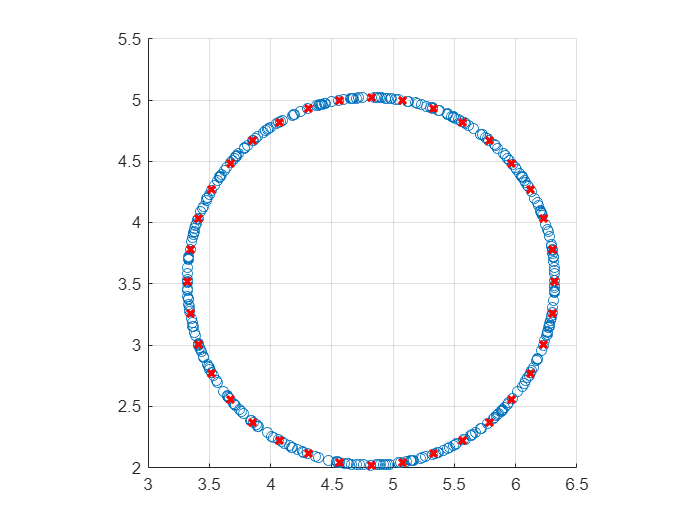

% Selecting the TIMIT/TEST dataset
folder = 'TIMIT/TEST';
fileListTest = dir(fullfile(folder, '**', '*.wav'));

sentencesXdoa = 10; % Number of sentences for each source location

numSentencesTest10 = sentencesXdoa * length(res10); % Total dataset size

% Randomly selecteing the indexes of the sentences
rng(13);
randIndexesTest10 = randi([1 length(fileListTest)], 1, numSentencesTest10);

% Extracing audio data
audioTest10 = extractAudio(fileListTest, randIndexesTest10, numSentencesTest10, maxDuration, fs);

% Generating the DOAs
radius = 1.5;
sourceCoordinatesTest10 = zeros([numSentencesTest10,2]);
randomDOAStest10 = zeros([numSentencesTest10,1]);

rng(7)
for i = 1:length(res10)
    for j = 1:sentencesXdoa
        index = (i-1)*sentencesXdoa + j;
        randomDOAStest10(index) = res10(i) + (rand - 0.5) * deg2rad(10);
        sourceCoordinatesTest10(index,1) = mic_center(1) + radius * cos(randomDOAStest10(index));
        sourceCoordinatesTest10(index,2) = mic_center(2) + radius * sin(randomDOAStest10(index));
    end   
end

% Plotting the microphones' plane, the red X represents a source location
figure;
scatter(sourceCoordinatesTest10(:,1), sourceCoordinatesTest10(:,2))
hold on
scatter(mic_center(1) + radius * cos(res10), mic_center(2) + radius * sin(res10), 'x','r', 'LineWidth',2)
grid on
pbaspect([1 1 1])

% Checking the dataset integrity
labelDOA10 = zeros(numSentencesTest10,1);
for i = 1:numSentencesTest10
    labelDOA10(i) = sourceClass(res10, randomDOAStest10(i));
    fprintf('DOA: %f --> %d --> %f\n', randomDOAStest10(i)/(2*pi)*360, labelDOA10(i), res10(labelDOA10(i))/(2*pi)*360);
end

DOA: 175.763083 --> 1 --> 180.000000
DOA: 182.799188 --> 1 --> 180.000000
DOA: 179.384092 --> 1 --> 180.000000
DOA: 182.234652 --> 1 --> 180.000000
DOA: 184.779895 --> 1 --> 180.000000
DOA: 180.384959 --> 1 --> 180.000000
DOA: 180.011205 --> 1 --> 180.000000
DOA: 175.720511 --> 1 --> 180.000000
DOA: 177.684390 --> 1 --> 180.000000
DOA: 179.998825 --> 1 --> 180.000000
DOA: 191.792300 --> 2 --> 190.000000
DOA: 193.037390 --> 2 --> 190.000000
DOA: 188.809411 --> 2 --> 190.000000
DOA: 185.659363 --> 2 --> 190.000000
DOA: 187.881456 --> 2 --> 190.000000
DOA: 194.095935 --> 2 --> 190.000000
DOA: 187.133854 --> 2 --> 190.000000
DOA: 189.521240 --> 2 --> 190.000000
DOA: 194.312060 --> 2 --> 190.000000
DOA: 185.248992 --> 2 --> 190.000000
DOA: 201.005489 --> 3 --> 200.000000
DOA: 204.501295 --> 3 --> 200.000000
DOA: 197.303029 --> 3 --> 200.000000
DOA: 200.484899 --> 3 --> 200.000000
DOA: 204.091284 --> 3 --> 200.000000
DOA: 196.331694 --> 3 --> 200.000000
DOA: 200.234126 --> 3 --> 200.000000
D

% Simulation
for i = 1:numSentencesTest10
    s = [sourceCoordinatesTest10(i,1), sourceCoordinatesTest10(i,2), 1.5]; % Source position [x y z] (m)
    h = rir_generator(c, fs, r, s, room_dim, T60, n, mtype, order, dim, orientation, hp_filter);

    maxSamples = fs * 0.5;
    currentAudio = audioTest10(1:maxSamples,i);

    filepath = 'MATLAB_TEST10';

    convAndSave(currentAudio, h, filepath, i, i, labelDOA10(i), labelDOA10(i), fs, maxSamples)

end

### Test dataset for resolution 30°

See previous test dataset's comments

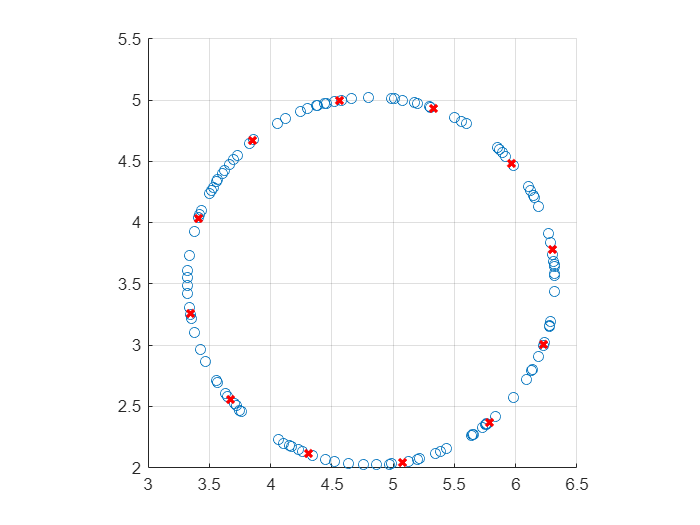

numSentencesTest30 = sentencesXdoa * length(res30);

rng(12);
randIndexesTest30 = randi([1 length(fileListTest)],1,numSentencesTest30);

audioTest30 = extractAudio(fileListTest, randIndexesTest30, numSentencesTest30, maxDuration, fs);

sourceCoordinatesTest30 = zeros([numSentencesTest30,2]);
randomDOAStest30 = zeros([numSentencesTest30,1]);


rng(3)
for i = 1:length(res30)
    for j = 1:sentencesXdoa
        index = (i-1)*sentencesXdoa + j;
        randomDOAStest30(index) = res30(i) + (rand - 0.5) * deg2rad(30);
        sourceCoordinatesTest30(index,1) = mic_center(1) + radius * cos(randomDOAStest30(index));
        sourceCoordinatesTest30(index,2) = mic_center(2) + radius * sin(randomDOAStest30(index));
    end   
end

figure;
scatter(sourceCoordinatesTest30(:,1), sourceCoordinatesTest30(:,2))
hold on
scatter(mic_center(1) + radius * cos(res30), mic_center(2) + radius * sin(res30), 'x','r', 'LineWidth',2)
grid on
pbaspect([1 1 1])

labelDOA30 = zeros(numSentencesTest30,1);
for i = 1:numSentencesTest30
    labelDOA30(i) = sourceClass(res30, randomDOAStest30(i));
    fprintf('DOA: %f --> %d --> %f\n', randomDOAStest30(i)/(2*pi)*360, labelDOA30(i), res30(labelDOA30(i))/(2*pi)*360);
end

DOA: 191.523937 --> 1 --> 190.000000
DOA: 196.244435 --> 1 --> 190.000000
DOA: 183.727142 --> 1 --> 190.000000
DOA: 190.324828 --> 1 --> 190.000000
DOA: 201.788409 --> 1 --> 190.000000
DOA: 201.888793 --> 1 --> 190.000000
DOA: 178.767559 --> 1 --> 190.000000
DOA: 181.217286 --> 1 --> 190.000000
DOA: 176.544016 --> 1 --> 190.000000
DOA: 188.224295 --> 1 --> 190.000000
DOA: 205.896286 --> 2 --> 220.000000
DOA: 218.704997 --> 2 --> 220.000000
DOA: 224.474321 --> 2 --> 220.000000
DOA: 213.354618 --> 2 --> 220.000000
DOA: 225.287647 --> 2 --> 220.000000
DOA: 222.725885 --> 2 --> 220.000000
DOA: 205.719456 --> 2 --> 220.000000
DOA: 221.765623 --> 2 --> 220.000000
DOA: 212.777573 --> 2 --> 220.000000
DOA: 217.453036 --> 2 --> 220.000000
DOA: 243.505752 --> 3 --> 250.000000
DOA: 255.794138 --> 3 --> 250.000000
DOA: 248.213612 --> 3 --> 250.000000
DOA: 239.706032 --> 3 --> 250.000000
DOA: 251.339471 --> 3 --> 250.000000
DOA: 258.409443 --> 3 --> 250.000000
DOA: 244.190906 --> 3 --> 250.000000
D

for i = 1:numSentencesTest30
    s = [sourceCoordinatesTest30(i,1), sourceCoordinatesTest30(i,2), 1.5]; % Source position [x y z] (m)
    h = rir_generator(c, fs, r, s, room_dim, T60, n, mtype, order, dim, orientation, hp_filter);

    maxSamples = fs * 0.5;
    currentAudio = audioTest30(1:maxSamples,i);

    filepath = 'MATLAB_TEST30';

    convAndSave(currentAudio, h, filepath, i, i, labelDOA30(i), labelDOA30(i), fs, maxSamples)
   
end

## Custom tests

In this section we generate the datasets for testing the generalization abilities of the NN. 

We will test the following parameters:

- Changing the receivers' position by moving it around the room

- Changing the distance (radially) of the sources from the microphones

- Changing room volume while mantaining the same shape

### Receiver position

In this dataset we move the experimental strumentation from the center of the room at mid height to top-right corner at floor height.

The range goes from the microphones' position of (4.82, 3.52, 1.5) [m] to (8, 5.4, 0.14) [m] subdivided in 10 equally spaced steps.

% Selecting the TIMIT/TEST dataset
folder = 'TIMIT/TEST';
fileListTest = dir(fullfile(folder, '**', '*.wav'));

fs = 16000;                 % Sample frequency (samples/s)
maxDuration = 2;            % Max duration of a sentence (s)

steps = 9; % Number of subdivisions of the testing range
numTests = steps + 1; % Number of tests
sentencesXtest = 10; % Number of sentences for each test

datesetSize = sentencesXtest * numTests; 

% Randomly selecteing the indexes of the sentences
rng(113);
randIndexes = randi([1 length(fileListTest)], 1, datesetSize);

% Extracting audio data
audioTest = extractAudio(fileListTest, randIndexes, datesetSize, maxDuration, fs);


delta = 0.14; % Delta introduced to not place the source into the wall
mic_cetner_f = [room_dim(1) - radius - delta, room_dim(2) - radius - delta, delta]; % Microphones final position
% Microphones' center position spanning linearly from the center of the room to the top right corner
% Height decreses lenearly also
mic_positions = [mic_center(1):(mic_cetner_f(1) - mic_center(1))/steps:mic_cetner_f(1); 
                 mic_center(2):(mic_cetner_f(2) - mic_center(2))/steps:mic_cetner_f(2);
                 mic_center(3):(mic_cetner_f(3) - mic_center(3))/steps:mic_cetner_f(3)];
mic_positions = transpose(mic_positions) % 1 test for each mic position --> 10 tests
% Generating random DOAs
randomDOAS = rand(datesetSize, 1) * 2 * pi; % in [rad]

for i = 1:numTests % For each test
    basepath = 'RECEIVER_POS';
    filepath = sprintf("%s/RP%i", basepath, i)

    currentMicPosition = mic_positions(i,:); % Select current mic center

mic_positions =     4.8200    3.5200    1.5000
    5.1733    3.7289    1.3489
    5.5267    3.9378    1.1978
    5.8800    4.1467    1.0467
    6.2333    4.3556    0.8956
    6.5867    4.5644    0.7444
    6.9400    4.7733    0.5933
    7.2933    4.9822    0.4422
    7.6467    5.1911    0.2911
    8.0000    5.4000    0.1400



    % Placing the microphones around the current center
    r = [currentMicPosition(1) + d/2, currentMicPosition(2),       currentMicPosition(3);   % Receivers positions (m)
         currentMicPosition(1),       currentMicPosition(2) + d/2, currentMicPosition(3);   % [x_1,  y_1,  z_1;  
         currentMicPosition(1) - d/2, currentMicPosition(2),       currentMicPosition(3);   %  x_2,  y_2,  z_2; 
         currentMicPosition(1),       currentMicPosition(2) - d/2, currentMicPosition(3);]; %  ...]    

    for j = 1:sentencesXtest % For each sentence
        index = (i - 1)*sentencesXtest + j;

        % Compute the coordinates of the source given the random DOA
        currentSourceCoordinate = zeros([1, 3]); % (x,y,z)
        currentSourceCoordinate(1,1) = currentMicPosition(1) + radius * cos(randomDOAS(index));
        currentSourceCoordinate(1,2) = currentMicPosition(2) + radius * sin(randomDOAS(index));
        currentSourceCoordinate(1,3) = currentMicPosition(3);

        % Apply labels
        labelDOA30 = sourceClass(res30, randomDOAS(index));
        labelDOA10 = sourceClass(res10, randomDOAS(index));

        % Simulate
        s = currentSourceCoordinate; % Source position [x y z] (m)
        h = rir_generator(c, fs, r, s, room_dim, T60, n, mtype, order, dim, orientation, hp_filter);

        maxSamples = fs * 0.5;
        currentAudio = audioTest(1:maxSamples,index);
        
        % Save
        convAndSave(currentAudio, h, filepath, i, index, labelDOA30, labelDOA10, fs, maxSamples)
    end
end

filepath = "RECEIVER_POS/RP1"

filepath = "RECEIVER_POS/RP2"

filepath = "RECEIVER_POS/RP3"

filepath = "RECEIVER_POS/RP4"

filepath = "RECEIVER_POS/RP5"

filepath = "RECEIVER_POS/RP6"

filepath = "RECEIVER_POS/RP7"

filepath = "RECEIVER_POS/RP8"

filepath = "RECEIVER_POS/RP9"

filepath = "RECEIVER_POS/RP10"

### Source distance

In this dataset we move radially the sources starting from near positions from the microphones' center to far positions.

The range of the source distance goes from 0.14 [m] to 6.94 [m] subdivided in 10 equally spaced steps.

% Selecting the TIMIT/TEST dataset
folder = 'TIMIT/TEST';
fileListTest = dir(fullfile(folder, '**', '*.wav'));

fs = 16000;                 % Sample frequency (samples/s)
maxDuration = 2;            % Max duration of a sentence (s)

steps = 9; % Number of subdivisions of the testing range
numTests = steps + 1; % Number of tests
sentencesXtest = 10; % Number of sentences for each test

datesetSize = sentencesXtest * numTests; 

% Randomly selecteing the indexes of the sentences
rng(114);
randIndexes = randi([1 length(fileListTest)], 1, datesetSize);

% Extracting audio data
audioTest = extractAudio(fileListTest, randIndexes, datesetSize, maxDuration, fs);

delta = 0.1; % Delta introduced to not place the sources into the wall
distance_i = d + delta; % Initial distance
distance_f = room_dim(2) - delta ; % Final distance
distances = distance_i:(distance_f - distance_i)/steps:distance_f % Equally spaced range form the mics center

distances =     0.1400    0.8956    1.6511    2.4067    3.1622    3.9178    4.6733    5.4289    6.1844    6.9400


% Generating random DOAs
randomDOAS = rand(datesetSize, 1) * 2 * pi; % in [rad]

for i = 1:numTests % For each test
    basepath = 'SOURCE_DISTANCE';
    filepath = sprintf("%s/SD%i", basepath, i)

    radius = distances(i) % Select the current distance of the source

    for j = 1:sentencesXtest % For each sentence
        index = (i - 1)*sentencesXtest + j;
        
        % Place source at the current distance from the center given the random DOA
        currentSourceCoordinate = zeros([1, 3]); % (x,y,z)
        currentSourceCoordinate(1,1) = mic_center(1) + radius * cos(randomDOAS(index));
        currentSourceCoordinate(1,2) = mic_center(2) + radius * sin(randomDOAS(index));
        currentSourceCoordinate(1,3) = mic_center(3);
        
        % Labeling data
        labelDOA30 = sourceClass(res30, randomDOAS(index));
        labelDOA10 = sourceClass(res10, randomDOAS(index));

        % Simulation
        s = currentSourceCoordinate; % Source position [x y z] (m)
        h = rir_generator(c, fs, r, s, room_dim, T60, n, mtype, order, dim, orientation, hp_filter);

        maxSamples = fs * 0.5;
        currentAudio = audioTest(1:maxSamples,index);
        
        % Convolution and saving
        convAndSave(currentAudio, h, filepath, i, index, labelDOA30, labelDOA10, fs, maxSamples)
    end
end

filepath = "SOURCE_DISTANCE/SD1"

radius = 0.1400

filepath = "SOURCE_DISTANCE/SD2"

radius = 0.8956

filepath = "SOURCE_DISTANCE/SD3"

radius = 1.6511

filepath = "SOURCE_DISTANCE/SD4"

radius = 2.4067

filepath = "SOURCE_DISTANCE/SD5"

radius = 3.1622

filepath = "SOURCE_DISTANCE/SD6"

radius = 3.9178

filepath = "SOURCE_DISTANCE/SD7"

radius = 4.6733

filepath = "SOURCE_DISTANCE/SD8"

radius = 5.4289

filepath = "SOURCE_DISTANCE/SD9"

radius = 6.1844

filepath = "SOURCE_DISTANCE/SD10"

radius = 6.9400

### Room volume

In this dataset we mantain the shape of the room while increasing linearly the three dimensions. Therefore the room's volume will increase exponentially, and the T60 will follow the same fashion. The assumption of the T60 has been made based on the Sabine's formula, which state the linear depence between the volume of the room and the T60.

For this particular dataset we make 20 tests with increasing values of the y dimension of the room. The constant aspect ratio will preserve the shape of the room.

steps = 19; % Number of subdivisions of the testing range
numTests = steps + 1; % Number of tests

volume = room_dim(1) * room_dim(2) * room_dim(3) % Current room volume corresponds to a T60 of 300ms
% Ratios between the dimensions will be kept constant to mantain the same
% sphape. Incresing linearly the y dim will increase equally the others

volume = 200.2035

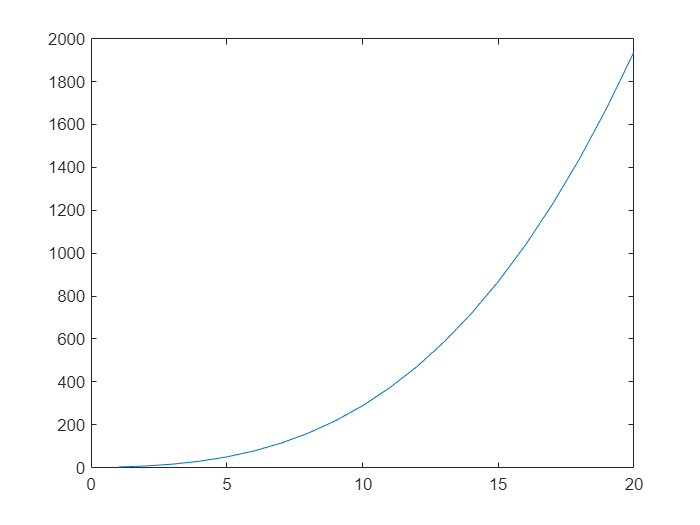

xy_ratio = room_dim(1) / room_dim(2);
zy_ratio = room_dim(3) / room_dim(2);

radius = 1.5;
y_i = radius + 0.1; % Initial y length [m]
y_f = 15; % Final y length [m]
y_steps = y_i:(y_f - y_i)/steps:y_f; % y dim range

room_test_dims = zeros([numTests, 3]);
volumes = zeros([numTests, 1]);
for i = 1:numTests
    room_test_dims(i,1) = xy_ratio * y_steps(i);
    room_test_dims(i,2) = y_steps(i);
    room_test_dims(i,3) = zy_ratio * y_steps(i);
    volumes(i, 1) = room_test_dims(i,1) * room_test_dims(i,2) * room_test_dims(i,3);
end

% Computing T60 that follows linearly the volume, rescaled in order to have
% T60 = 300 ms for the room of volume 200 m^2 which is our initial room
t60_volumes = volumes/1000 + 0.09;

% Plotting volume for each test
figure
plot(volumes)
for i = 1:numTests
    fprintf("Room %i has dims [%f, %f, %f] [m] = volume %f m^3--> t60 %f s\n", i, room_test_dims(i,1), ...

        room_test_dims(i,2), room_test_dims(i,3), volumes(i), t60_volumes(i))
end

Room 1 has dims [2.190909, 1.600000, 0.670455] [m] = volume 2.350248 m^3--> t60 0.092350 s
Room 2 has dims [3.156639, 2.305263, 0.965984] [m] = volume 7.029351 m^3--> t60 0.097029 s
Room 3 has dims [4.122368, 3.010526, 1.261513] [m] = volume 15.656007 m^3--> t60 0.105656 s
Room 4 has dims [5.088098, 3.715789, 1.557042] [m] = volume 29.437914 m^3--> t60 0.119438 s
Room 5 has dims [6.053828, 4.421053, 1.852572] [m] = volume 49.582770 m^3--> t60 0.139583 s
Room 6 has dims [7.019557, 5.126316, 2.148101] [m] = volume 77.298274 m^3--> t60 0.167298 s
Room 7 has dims [7.985287, 5.831579, 2.443630] [m] = volume 113.792126 m^3--> t60 0.203792 s
Room 8 has dims [8.951017, 6.536842, 2.739160] [m] = volume 160.272022 m^3--> t60 0.250272 s
Room 9 has dims [9.916746, 7.242105, 3.034689] [m] = volume 217.945663 m^3--> t60 0.307946 s
Room 10 has dims [10.882476, 7.947368, 3.330218] [m] = volume 288.020746 m^3--> t60 0.378021 s
Room 11 has dims [11.848206, 8.652632, 3.625748] [m] = volume 371.704970 m^3

From the previous we can see that we start with a small room which is not very reverberant and we finish with a very boog room with hight T60. The Sabine's formula has been exploited to maintain a certain degree of plausibility.

% Selecting the TIMIT/TEST dataset
folder = 'TIMIT/TEST';
fileListTest = dir(fullfile(folder, '**', '*.wav'));

fs = 16000;                 % Sample frequency (samples/s)
maxDuration = 2;            % Max duration of a sentence (s)

sentencesXtest = 10;

datesetSize = sentencesXtest * numTests; 

% Randomly selecteing the indexes of the sentences
rng(313);
randIndexes = randi([1 length(fileListTest)], 1, datesetSize);

audioTest = extractAudio(fileListTest, randIndexes, datesetSize, maxDuration, fs);

% Generating random DOAS
randomDOAS = rand(datesetSize, 1) * 2 * pi; % in [rad]

for i = 1:numTests
    basepath = 'ROOM_VOLUME';
    filepath = sprintf("%s/RV%i", basepath, i)
    mkdir(filepath)

    room_dim = room_test_dims(i,:); % Selcting current room dimentions

    d = 0.04;   % Diameter of the microphone array
    mic_center = [room_dim(1)/2 room_dim(2)/2 room_dim(3)/2]; % Placing the microphones at the center
    r = [mic_center(1) + d/2, mic_center(2),       mic_center(3);   % Receivers positions (m)
         mic_center(1),       mic_center(2) + d/2, mic_center(3);   % [x_1,  y_1,  z_1;  
         mic_center(1) - d/2, mic_center(2),       mic_center(3);   %  x_2,  y_2,  z_2; 
         mic_center(1),       mic_center(2) - d/2, mic_center(3);]; %  ...]   

    T60 = t60_volumes(i) % Selecting T60 that corresponds to the current room

    % Simulate and save
    for j = 1:sentencesXtest
        index = (i - 1)*sentencesXtest + j;
        currentSourceCoordinate = zeros([1, 3]); 
        currentSourceCoordinate(1,1) = mic_center(1) + radius * cos(randomDOAS(index));
        currentSourceCoordinate(1,2) = mic_center(2) + radius * sin(randomDOAS(index));
        currentSourceCoordinate(1,3) = mic_center(3);

        labelDOA30 = sourceClass(res30, randomDOAS(index));
        labelDOA10 = sourceClass(res10, randomDOAS(index));

        s = currentSourceCoordinate; 
        h = rir_generator(c, fs, r, s, room_dim, T60, n, mtype, order, dim, orientation, hp_filter);

        maxSamples = fs * 0.5;
        currentAudio = audioTest(1:maxSamples,index);
        
        convAndSave(currentAudio, h, filepath, i, index, labelDOA30, labelDOA10, fs, maxSamples)
    end
end

filepath = "ROOM_VOLUME/RV1"

T60 = 0.0924

filepath = "ROOM_VOLUME/RV2"

T60 = 0.0970

filepath = "ROOM_VOLUME/RV3"

T60 = 0.1057

filepath = "ROOM_VOLUME/RV4"

T60 = 0.1194

filepath = "ROOM_VOLUME/RV5"

T60 = 0.1396

filepath = "ROOM_VOLUME/RV6"

T60 = 0.1673

filepath = "ROOM_VOLUME/RV7"

T60 = 0.2038

filepath = "ROOM_VOLUME/RV8"

T60 = 0.2503

filepath = "ROOM_VOLUME/RV9"

T60 = 0.3079

filepath = "ROOM_VOLUME/RV10"

T60 = 0.3780

filepath = "ROOM_VOLUME/RV11"

T60 = 0.4617

filepath = "ROOM_VOLUME/RV12"

T60 = 0.5602

filepath = "ROOM_VOLUME/RV13"

T60 = 0.6747

filepath = "ROOM_VOLUME/RV14"

T60 = 0.8065

filepath = "ROOM_VOLUME/RV15"

T60 = 0.9567

filepath = "ROOM_VOLUME/RV16"

T60 = 1.1265

filepath = "ROOM_VOLUME/RV17"

T60 = 1.3172

filepath = "ROOM_VOLUME/RV18"

T60 = 1.5300

filepath = "ROOM_VOLUME/RV19"

T60 = 1.7660

filepath = "ROOM_VOLUME/RV20"

T60 = 2.0265

# Functions definitions

Auxiliary functions definition:

function [candidateClass] = sourceClass(candidates, target)
    % Return class of the nearest candidate source location
    % Candidates angles and target angle are in grades
    
    distance = zeros(size(candidates));
    
    for i = 1:length(candidates)
        distance(i) = abs(candidates(i) - target);
    end
    [~, index] = min(distance);
    
    % Check classification for the discontinuity at 360° --> 0°
    % Discontinuity alwys at length(candidates) / 2
    % If the found class is at the discontiuity, compute the distance 
    % considering the next source location incrementally (continuity)
    if index == length(candidates) / 2
        distDiscont = abs(candidates(index + 1) + 2 * pi - target);
        if distDiscont < distance(index)
            index = index + 1;
        end 
    end

candidateClass = index;
end



function audioSamples = extractAudio(fileList, randIndexes, numSelectedSentences, maxDuration, fs)

    audioSamples = zeros([maxDuration*fs, numSelectedSentences]);

    for i = 1:numSelectedSentences
        [audio, ~] = audioread(append(fileList(randIndexes(i)).folder, '\', fileList(randIndexes(i)).name));
        %audioSamples(:,i) = [audio; zeros([fs*maxDuration - length(audio), 1])];
        if length(audio) < maxDuration*fs
            audio = [audio; zeros([fs*maxDuration - length(audio), 1])];
        else 
            audio = audio(1:maxDuration*fs);
        end
        audioSamples(:,i) = audio;
    end
end

function generateDataset(filepath, audioSamples, numSelectedSentences, DOASxSentence, targetDatasetSize, randomDOAS, res30, res10, sourceCoordinates, c, fs, r, room_dim, T60, n, mtype, order, dim, orientation, hp_filter)
    for i = 1:numSelectedSentences
        % Compute for DOASxSentece different source locations
        for j = 1:DOASxSentence
            targetSetIdx = (i - 1) * DOASxSentence + j;
            fprintf('%.2f %% \n', targetSetIdx/targetDatasetSize*100);
            
            labelDOA30 = sourceClass(res30, randomDOAS(targetSetIdx));
            labelDOA10 = sourceClass(res10, randomDOAS(targetSetIdx));
            
            fprintf('DOA: %f\n', randomDOAS(targetSetIdx)/(2*pi)*360);
            fprintf('label 30: %.2f\n', res30(labelDOA30)/(2*pi)*360);
            fprintf('label 10: %.2f\n', res10(labelDOA10)/(2*pi)*360);
            fprintf('\n');
            
            s = [sourceCoordinates(targetSetIdx,1), sourceCoordinates(targetSetIdx,2), 1.5]; % Source position [x y z] (m)
            h = rir_generator(c, fs, r, s, room_dim, T60, n, mtype, order, dim, orientation, hp_filter);

            maxSamples = fs * 0.5;
            currentAudio = audioSamples(1:maxSamples,i);

            convAndSave(currentAudio, h, filepath, i, targetSetIdx, labelDOA30, labelDOA10, fs, maxSamples)
   
        end
    end
end

function convAndSave(currentAudio, h, filepath, id, sampleNum, labelDOA30, labelDOA10, fs, maxSamples)
    % Applying RiR and cutting at 500ms
    micA = conv(h(1,:), currentAudio);
    micA = micA(end-maxSamples+1:end);
    micB = conv(h(2,:), currentAudio);
    micB = micB(end-maxSamples+1:end);
    micC = conv(h(3,:), currentAudio);
    micC = micC(end-maxSamples+1:end);
    micD = conv(h(4,:), currentAudio);
    micD = micD(end-maxSamples+1:end);

    % Filename structure: SA{ID}-{MIC}-{SAMPLE NUM}-{CLASS30}-{CLASS10}.wav
    % NB: classes' names are from 0 to K - 1, while MATLABS start form 1
    filenameMicA = sprintf('%s/SA-%i-A-%i-%i-%i.wav', filepath, (sampleNum - 1) * 4 + 0, id - 1, labelDOA30 - 1, labelDOA10 - 1 );
    audiowrite(filenameMicA, micA, fs);
    filenameMicB = sprintf('%s/SA-%i-B-%i-%i-%i.wav', filepath, (sampleNum - 1) * 4 + 1, id - 1, labelDOA30 - 1, labelDOA10 - 1 );
    audiowrite(filenameMicB, micB, fs);
    filenameMicC = sprintf('%s/SA-%i-C-%i-%i-%i.wav', filepath, (sampleNum - 1) * 4 + 2, id - 1, labelDOA30 - 1, labelDOA10 - 1 );
    audiowrite(filenameMicC, micC, fs);
    filenameMicD = sprintf('%s/SA-%i-D-%i-%i-%i.wav', filepath, (sampleNum - 1) * 4 + 3, id - 1, labelDOA30 - 1, labelDOA10 - 1 );
    audiowrite(filenameMicD, micD, fs);
end